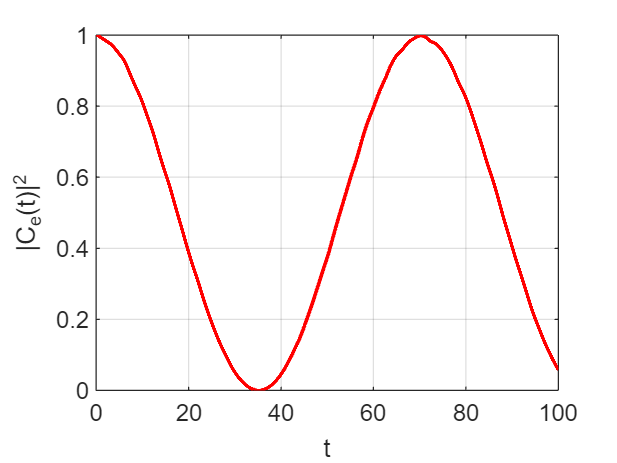

% Clear workspace, command window, and close all figures
clear;
clc;
close all;


% Parameters
N = 5; % Example value, you can change it
g = 0.1;   % Coupling strength g
J = 2;   % Coupling constant J
J_prime = 1; % Coupling constant J'
omega = 5; % Modulation frequency omega
Delta = - omega * 0.2;  % Detuning parameter Delta
V = 0.2;   % Modulation amplitude V
j_0 = (N-1)/2;

dt = 0.01;  % Time step for numerical integration
T = 100;   % Total simulation time
% Time vector
time = 0:dt:T;
num_steps = length(time);


% Define the Hamiltonian function
Ht = @(t) Hamilontian(t, N, J, J_prime, V, omega, g, Delta);

% Initialize the qubit in the excited state
psi_0 = zeros(2*N+1, 1);
psi_0(end) = 1;



% 调用runge_kutta_solver函数
psi_t = runge_kutta_timedependent(Ht, psi_0, time);



% Plot |C_e(t)|^2 vs time
figure;
plot(time, abs(psi_t(end, :)).^2, 'r', 'LineWidth', 1.5);
xlabel('t');
ylabel('|C_{e}(t)|^2');
grid on;

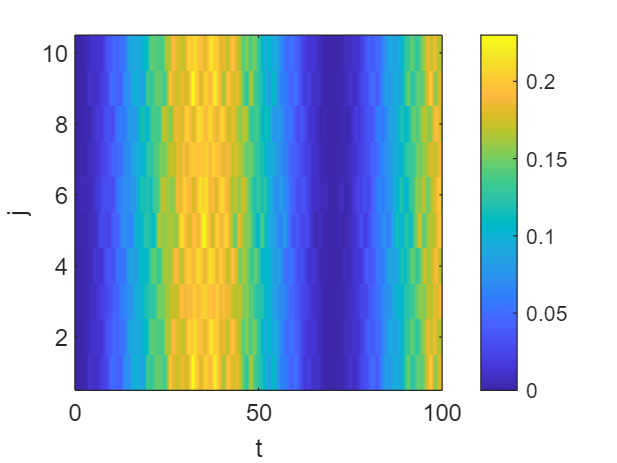


kk = linspace(-pi, pi, N);
E = sqrt((J^2 + J_prime^2) + 2*J*J_prime.*cos(kk));
theta = angle((J+J_prime.*exp(1i .* kk)) ./ E);
Gamma = (J+J_prime) * V .* sin(kk) ./ E;
delta = E - (omega / 2);
phi = atan(Gamma ./ delta);
tilde_E = sqrt(delta.^2 + Gamma.^2);


psi_pq = psi_t;
% p,q ---> u',v'
psi_uv = zeros(2*N+1,num_steps);
for i = 1:N
    psi_uv(2*i-1,:) = cos(phi(i)/2) * psi_pq(2*i-1,:) + sin(phi(i)/2) * psi_pq(2*i,:);
    psi_uv(2*i,:) = -1i * (sin(phi(i)/2) * psi_pq(2*i-1,:) - cos(phi(i)/2) * psi_pq(2*i,:));
end

% rorating frame u' ---> u
rotating = zeros(2*N+1, num_steps);
tu = exp(- 1i * omega /2 .* time);
tv = exp(1i * omega /2 .* time);
rotating(1:2:2*N,:) = repmat(tu, N, 1);
rotating(2:2:2*N,:) = repmat(tv, N, 1);
psi_uv = rotating .* psi_uv;


% u,v ---> a,b
psi_ab = zeros(2*N+1,num_steps);
for i = 1:N
    psi_ab(2*i-1,:) = exp(-1i * theta(i)) * (psi_uv(2*i-1,:) - psi_uv(2*i,:)) / sqrt(2);
    psi_ab(2*i,:) = (psi_uv(2*i-1,:) + psi_uv(2*i,:)) / sqrt(2);
end


% Fourier transform a_k ---> a_x
psi_ab_x = zeros(2*N);
k = linspace(-pi, pi, N);
x = (-(N-1)/2:(N-1)/2)';
fft = exp(1i .* kron(x, k)) / sqrt(N);
for i = 1:num_steps
    psi_ab_x(1:2:2*N-1, i) = fft * psi_ab(1:2:2*N-1,i); % a_k ---> a_x
    psi_ab_x(2:2:2*N, i) = fft * psi_ab(2:2:2*N,i); % b_k ---> b_x
end

% Plot |B_j(t)|^2 as a heatmap
figure;
imagesc(time, 1:2*N, abs(psi_ab_x).^2);
colorbar;
xlabel('t');
ylabel('j');
set(gca, 'YDir', 'normal'); % Ensure y-axis is correctly oriented


% Define function for the derivative
H2 = Ht(1)

H2 =   -1.5000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0253 + 0.0189i
  -0.0000 + 0.0000i   1.5000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0189 - 0.0253i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.3142 + 0.0000i  -0.2072 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0145 + 0.0416i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.2072 + 0.0000i   0.3142 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0047 - 0.0061i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.5000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   

function H = Hamilontian(t, N, J, J_prime, V, omega, g, Delta)
    kk = linspace(-pi, pi, N);
    E = sqrt(J^2 + J_prime^2 + 2*J*J_prime.*cos(kk));
    theta = angle((J+J_prime.*exp(1i * kk)) ./ E);
    Im_lambda = (J+J_prime) .* sin(kk) ./ E;
    phi = atan(Im_lambda./ (E-omega/2));

    % Create the Hamiltonian matrix
    H = zeros(2*N + 1); % Include additional state for the qubit
    Lambda = zeros(2*N + 1);
    H(end, end) = Delta;
    Lambda(end, end) = 1;
    for i = 1:1:N
        E_k = E(i);
        theta_k = theta(i);
        phi_k = phi(i);
        I_lambda = Im_lambda(i);
        H(2*i-1,2*i-1) = E_k - omega / 2; %mode p_k^dagger p_k
        H(2*i-1,2*i) = 1i * V * I_lambda; %mode p_k^dagger q_k
        H(2*i,2*i-1) = - 1i *  V * I_lambda; %mode q_k^dagger p_k
        H(2*i,2*i) = - E_k + omega / 2; % mode q_k^dagger q_k
        
        H(end, 2*i-1) = g * exp(-1i * theta_k) * exp(-1i * omega *t / 2) / sqrt(2*N);
        H(2*i-1, end) = g * exp(1i * theta_k) * exp(1i * omega *t / 2) / sqrt(2*N);
        H(end, 2*i) = - g * exp(-1i * theta_k) * exp(1i * omega *t / 2) / sqrt(2*N);
        H(2*i, end) = - g * exp(1i * theta_k) * exp(-1i * omega *t / 2) / sqrt(2*N);
        
        Lambda(2*i-1, 2*i-1) = cos(phi_k/2);
        Lambda(2*i-1, 2*i) = sin(phi_k/2);
        Lambda(2*i, 2*i-1) = - 1i * sin(phi_k/2);
        Lambda(2*i, 2*i) = 1i * cos(phi_k/2);

        
        

    end

    H = Lambda' * H * Lambda;

end



